Load file, signal should be in array. variable for the eeg should be called "clean" (or updated)

Example with single channel of UW data

clear all

tic

%files = dir('*.mat')

%load('B30_seizures_array_2long.mat')

%clean2 = clean;

isnan will remove all nan(not-a-number) entries; this happens in some of the really high noise/artifact areas




FileList = dir('*.mat');
disp('files in pathway:     ')

files in pathway:     


disp(numel(FileList))

     3



for a=1:numel(FileList)
    readout={a FileList(a).name};
    disp(readout)
end

    [1]    'A1_SigSumm_Ch1-32_noclean…'

    [2]    'A1_allChannels.mat'

    [3]    'A1_allChannels_clean.mat'




g = input ('which files?     ');


for k = g;


    
      input_name = FileList(k).name;            
        [~, name, ~] = fileparts (input_name); 
        
        load(FileList(k).name);

EEG(isnan(EEG)) = 0;

EEG2 = EEG;


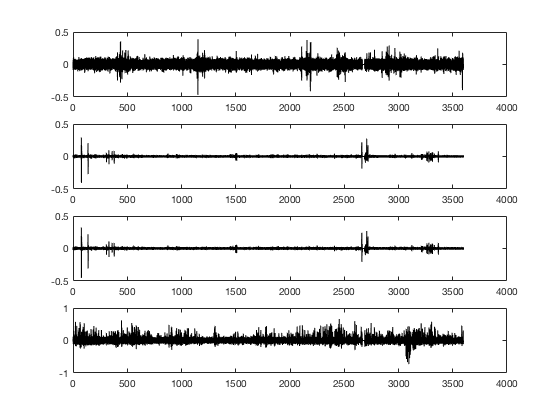


for col = 1:4

%plot(clean(:,col))
%hold on
    noise = find(abs(EEG(:,col))>1);
   
    if isempty(noise)==0  
     
        LengthNoise = length(noise);
        discon = zeros(LengthNoise,1);
        
        for n = 2:LengthNoise
            discon(n-1) = noise(n)-noise(n-1);   
        end
        
            jump = find(discon>(1*1024));
          
            jump = [0;jump];
            yy = length(jump);
        
            if yy > 1
            %clean(noise(1:jump(1))) = 0;
                for nn = 2:yy
                
                    
                    Start = noise(jump(nn-1)+1)-10240;
                    Stop = noise(jump(nn))+10240;
                   
                    if Start <=0
                        Start = 1;
                    else end
                    
                    EEG(Start:Stop,col) = 0;
                    %EEG(((noise(jump(nn-1)+1)-10240):noise(jump(nn))+10240),1:4) = 0;
                
                end
                EEG(noise(jump(yy)+1)-10240:noise(LengthNoise)+10240,1:4) = 0;
            %elseif yy==1
                %clean(noise(jump(1)-10240):noise(LengthNoise)+102040,:) = 0;
            else
            %elseif yy==0
            end
    else
    end
%    plot(clean(:,col))

clean = EEG;

clear discon noise jump n yy LengthNoise
    
end

tt = length(EEG);
t = 1/1024:1/1024:tt/1024;


    figure 
    title (name)
    subplot (4,1,1)
    plot(t, EEG(:,1),'k')
    subplot (4,1,2)
    plot(t, EEG(:,2),'k')
    subplot (4,1,3)
    plot(t, EEG(:,3),'k')
    subplot (4,1,4)
    plot(t, EEG(:,4),'k')

    saveas(gcf, [name '_postfig.eps']);

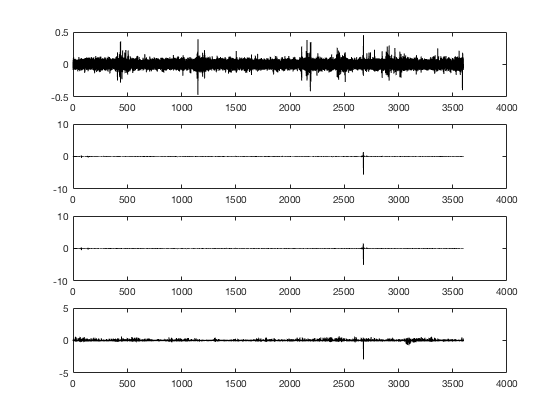

    
    figure 
    title (name)
    subplot (4,1,1)
    plot(t, EEG2(:,1),'k')
    subplot (4,1,2)
    plot(t, EEG2(:,2),'k')
    subplot (4,1,3)
    plot(t, EEG2(:,3),'k')
    subplot (4,1,4)
    plot(t, EEG2(:,4),'k')
    
    
saveas(gcf, [name '_prefig.eps']);


%close(gcf)

    save([name '_clean.mat'],'EEG');
    
  %  clear clean EEG
    
end

 